# Generating Surface Meshes and Calculating Metrics for a subset of dying cells

This script generates cell surface meshes for a set of taste cells that are dying but that have not had their lysosomes segmented. The metrics calculate from these cells will be used to increase our *n* in the statistical analysis of cell size. 

Since these cells do not have their lysosomes, we did not add their information to the idT table or their traces to the main VL table. Instead we created a dcT table and used that table to generate a separate VL table that will be used only in this script.

Refer to the [generate_cellMesh_cellT.mlx](matlab:open('./generate_cellMesh_cellT.mlx')) script for more details on cell mesh generation. 

NOTE: only run this script after running the [generate_cellMesh_cellT.mlx](matlab:open('./generate_cellMesh_cellT.mlx')) and generating the meshT table there.

REQUIREMENTS: 

- ManifoldPlus [https://github.com/hjwdzh/ManifoldPlus](https://github.com/hjwdzh/ManifoldPlus) 

- pyMeshFix: [https://pymeshfix.pyvista.org](https://pymeshfix.pyvista.org)

- Mathworks Lidar Toolbox

- MatGeom Toolbox (meshVolume function)

## Set-up

clearvars -except paths
close all
clc

### Path to manifoldPlus

Update:

- reconstruct path: contains folder with Reconstruct Data

-  manifoldPlus path for your local installation (../ManifoldPlus/build/manifold)

paths.reconstruct = "/Users/ernesto/Documents/WORK/Research/Finger Lab/Dying Cell Project/reconstruct data";
paths.manifoldPlus = "/Users/ernesto/github/ManifoldPlus/build/manifold";

## Load Reconstruct Data and generate VL table

### Get Cell Dying ID Table

This table contains the names of a dying cells to be modeled

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 5, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["ID", "Object", "Type", "Health", "TB"];
opts.VariableTypes = ["string", "string", "categorical", "categorical", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["ID", "Object"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["ID", "Object", "Type", "Health"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "TB", "TrimNonNumeric", true);
opts = setvaropts(opts, "TB", "ThousandsSeparator", ",");

% Import the data
didT = readtable("/Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/dying_list.csv", opts);

% Clear temporary variables
clear opts

% Display results
didT

#### Overlapping cells

The following two cells are found in both datasets. This will need be dealt with

la = ismember(didT.Cell,dcT.Object);

ans = 2×1 string array
    "TB2_TCdying-01_cw"
    "TB2_TCdying-02_cw"


didT.Cell(la)

### Get SL and TL

*series list* and *trace list*

folder_name = "Courtney_TF21"

folder_name = "Courtney_TF21"

paths.series = fullfile(paths.reconstruct, folder_name);
load_last = true; % load last saved file --- faster

[SL, TL] = get_series_contents(paths.series,load_last); % true input means load mat files instead

loading saved trace and series info...


### Get fTL

*filtered trace list*

- Set the Object names to import. 

- The following objects are all dying cells:

filter_str = didT.Object;
fTL = filter_trace_list(SL,TL, filter_str,true); % true means exact match
fTL.Properties.Description = 'dying_cells'; % modifies file name to keep projects separate

#### id missing objects

la = ismember(didT.Object, fTL.Object);
disp(didT.Object(~la))

- if no output, no missing objects

### get vl

vl = get_verTCs(SL,fTL,true);

VL loaded from File


### Convert to microns

img_mag = vl.Properties.UserData.img_mag;
vl(:,["x","y","z"]) = varfun(@(x) x * img_mag,vl,InputVariables=["x","y","z"]); % convert to microns

cellNames = ["TB1_AP13_EM"; "TB3_TC04"; "TB3_TC05";]

## Generate Dying Cell Meshes

- no lysosomes in this dataset

- resets volume calc in dcmT (if already calculated)

dcmT = genDyingCellMesh(vl,didT, paths); % dying cell meshT

          ID           Type    Health    VolAS     VolMP     VolFX     Method
    _______________    ____    ______    ______    ______    ______    ______

    "TB2_TCdying01"    x       late      149.89     403.6    403.03     "mp" 
    "TB2_TCdying02"    x       late      249.22    457.08    456.91     "mp" 
    "TB3_TC01"         x       late      246.54    446.93    446.92     "mp" 
    "TB3_TC02"         II      early     797.71    943.65    967.71     "mp" 
    "TB3_TC03"         III     early     1057.5    1310.5    1309.2     "mp" 
    "TB3_TC04"         II      early      333.2      1677    1676.2     "mp" 
    "TB3_TC05"         II      early     546.96    1854.5    1855.2     "mp" 
    "TB3_TC06"         III     early     508.19    1219.7  

disp(dcmT)

save(dcmT.Properties.UserData.filePath,"dcmT")

### Load dcmT if needed

load(fullfile(paths.cellMesh, "dcmT.mat"),"-mat","dcmT")

## Inspect Cell Meshes

Once **generateCellMeshes** is complete, it is critical to inspect all of the meshes, especially those that have radically different volume calculations between the various methods.  

1. TB3_TC02_as.obj - 0


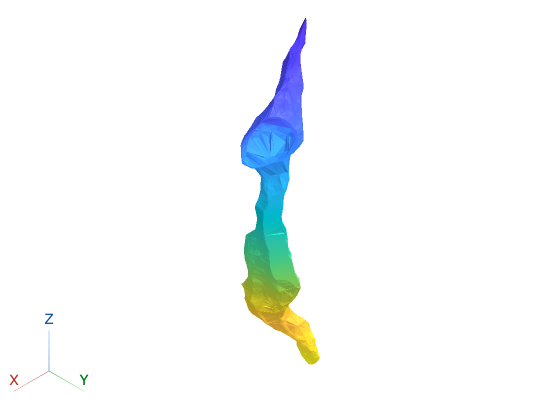

2. TB3_TC02_fx.obj - 0
3. TB3_TC02_mp.obj - 0


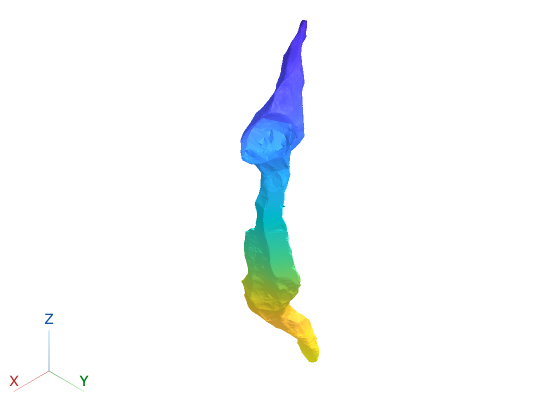

ans =   LinkProp with properties:

          Enabled: 'on'
    PropertyNames: {'CameraPosition'  'CameraZoom'}
          Targets: [1×3 Viewer3D]


dcmT_row = 4; % row in dcmT
hvwr = displayCellMeshes(dcmT.Cell(dcmT_row),paths.cellMesh);

- all Cell Dying Cell Meshes appear to be well represented by the MP method

- Copy the meshes 

### Recalculate Cell Meshes

cellName = dcmT.Cell(dcmT_row);
polarity = 1;
aRadius = 3; % nan if base input wanted
dcmt = generateSingleCellMesh(vl,didT, dcmT,paths, cellName, polarity, aRadius);

       Cell       Type    Health    Method    Polarity    AlphaRadius    VolAS     VolMP     VolFX 
    __________    ____    ______    ______    ________    ___________    ______    ______    ______

    "TB3_TC02"     II     early      "mp"        1            NaN        797.71    943.65    967.71

       Cell       Type    Health    Method    Polarity    AlphaRadius    VolAS     VolMP     VolFX 
    __________    ____    ______    ______    ________

### Update dcmT as needed

dcmT(dcmT_row,:) = dcmt;

## Calculate Dying Cell Metrics

### load dcmT if needed

load(fullfile(paths.cellMesh,"dcmT.mat"),"-mat","dcmT")

### Calculate Cell Metrics from Cell Meshes

dyingT = calcCellMetrics(dcmT);

dyingT.Properties.UserData.filePath = fullfile(paths.lysosome,"dyingT.mat");
dyingT.Properties.UserData.meshPath = paths.cellMesh;

dyingT.Type = categorical(dyingT.Type);
dyingT.Health = categorical(dyingT.Health);
type = dyingT.Type;
type(dyingT.Health=="early") = 'ed';
type(dyingT.Health=="late") = 'ld';
dyingT.PlotSort = categorical(type,{'IV','III','II','I','ld','ed'},'ordinal',true);

### Exclude TB2 rows from analysis

- They will be captured in the ***cellT*** dataset

la_tb2 = contains(dcmT.Cell,"TB2");
dyingT(la_tb2,:) = [];

### save dyingT table

save(dyingT.Properties.UserData.filePath,"dyingT")

# Local Functions

## Generate Cell Meshes

Also calculates volumes for each mesh

function [dcmT] = genDyingCellMesh(vl,didT, paths)
%GET_CELL_METRICS. Calculates the volume of each cell

arguments
    vl table % vertices list table
    didT table % dying cell id table
    paths struct % contains project relevant paths
end

% suppress alpha shape warnings
id = 'MATLAB:alphaShape:DupPointsBasicWarnId';
warning('off',id);

[cellID] = unique(didT.ID);

if exist(fullfile(paths.cellMesh,"dcmT.mat"),'file') % start with meshT
    fprintf('dcmT file found and loaded. Using this table for the analysis.')
    load(fullfile(paths.cellMesh,"dcmT.mat"),"-mat","dcmT")
    dcmT{:,{'VolAS','VolMP','VolFX'}} = nan(height(meshT),3);
    count=height(dcmT);
else
    didT = sortrows(didT,["Type","Health"]);
    dcmT = didT(:,{'Cell','Type','Health'});
    count=height(dcmT);
    dcmT.Method = repmat("mp",count,1);
    dcmT.Polarity = ones(count,1);
    dcmT = [dcmT array2table(nan(count,4),'VariableNames',["AlphaRadius","VolAS","VolMP","VolFX"])];
end

hwb = waitbar(0,"Please Wait");
for n=1:count
    fprintf("%d. %s\n",n,cellID(n))

    mesh_name = cellID(n);
    la = didT.ID == mesh_name; % returns cell names and bits
    la = ismember(vl.Object,didT.Object(la));

    vCell = (vl{la,["x" "y" "z"]});
    vCell = realign_vCell(vCell); 

 % calculate alphaShape and then surface mesh object
    if isnan(dcmT.AlphaRadius(n))
        shp = alphaShape(vCell); % no alpha radius inputted - the default
    else
        shp = alphaShape(vCell,dcmT.AlphaRadius(n));
    end

    [volMP, volFX] = getWaterTightMesh(shp,mesh_name, paths);

    dcmT.VolAS(n) = shp.volume;
    dcmT.VolMP(n) = volMP;
    dcmT.VolFX(n) = volFX;
       
    waitbar(n/count, hwb,sprintf('%d. %s',n,mesh_name))
end

dcmT.Properties.UserData.filePath = fullfile(paths.cellMesh,"dcmT.mat");
dcmT.Properties.UserData.meshPath = paths.cellMesh;
dcmT.Properties.UserData.fdec = ["as" "mp" "fx"]; %as=alphaShape, mp=manifoldPlus, fx=meshFix
dcmT.Properties.UserData.ext = ".obj";
delete(hwb)

end

## Generate Single Cell Mesh

Specific to dying cells because of the different vl table

function [mt, srow] = generateSingleCellMesh(vl,didT, dcmT,paths, cellName, Polarity, AlphaRadius)
%GENERATECELLMESH Generates meshes for the selected mesh.  Assumes VL contains lysosome structures

arguments
    vl table % vertices list
    didT table % id Table (helps find the bits)
    dcmT table  % meshT table with info regarding cell to reconstruct
    paths struct % paths structure
    cellName {mustBeText}
    Polarity {mustBeNumeric,mustBeScalarOrEmpty}
    AlphaRadius {mustBeNumeric,mustBeScalarOrEmpty}
end

srow = find(dcmT.Cell==cellName);
mt = dcmT(srow,:);
disp(mt)
mt.Polarity = Polarity; % flip cell up
mt.AlphaRadius = AlphaRadius; % increase to close hole

la = didT.ID == cellName; % returns cell names and bits
la = ismember(vl.Object,didT.Object(la));

vCell = (vl{la,["x" "y" "z"]});
vCell = realign_vCell(vCell);

% calculate alphaShape and then surface mesh object
if isnan(mt.AlphaRadius)
    shp = alphaShape(vCell); % no alpha radius inputted - the default
else
    shp = alphaShape(vCell,mt.AlphaRadius);
end
[volMP, volFX] = getWaterTightMesh(shp,mt.Cell, paths);
mt.VolAS = shp.volume;
mt.VolMP = volMP;
mt.VolFX = volFX;
disp(mt)
end

## Realign Vertices to Axes

function vCell = realign_vCell(vCell)
% transform vertices
vCell = vCell - mean(vCell);

[~,~,V]=svd(vCell,0); % Find the direction of most variance
vCell =  vCell * V;

% align to z-axis
% angl = 90 * polarity;
vCell = mmRotateSurfaceVertices(vCell,'y',90);

% rotate around z-axis
vCell = mmRotateSurfaceVertices(vCell,'z',90);
end